syms kxa 
Z=50;
c=3e8;
a=0.04;
C=8.47*1e-12;
x1=exp(-1i*kxa);
x2=exp(1i*kxa);
n=100;
m=100;
Result1=zeros(3*n,3);
Result2=zeros(n*m,3);
count=1;

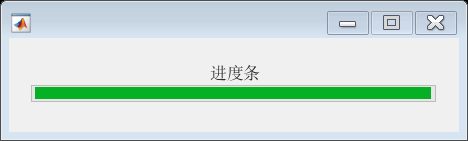

for omega=linspace(0,2*pi*1e9,n)
    k=omega/c;
    Ya=1i*omega*C;
    Yb=-Ya;
    Yc=2*Ya;
    X=[Ya Yb 0;Yb Yc Yb;0 Yb Ya];
    Th=[cos(k*a/2)*eye(3) 1i*Z*sin(k*a/2)*eye(3);1i*sin(k*a/2)*eye(3)/Z cos(k*a/2)*eye(3)];
    Tv=[eye(3) zeros(3);X eye(3)];
    T=Th*Tv*Th;
    for kya = linspace(-pi,pi,m)
        y=exp(-1i*kya);
        E=diag([x1,y,x2,x1,y,x2]);
        equ=det(T-E)==0;
        r=solve(equ,kxa);
        Result2(count,:)=[omega,double(r),kya];
        count=count+1;
        waitbar(count/n/m)
        drawnow
    end
end

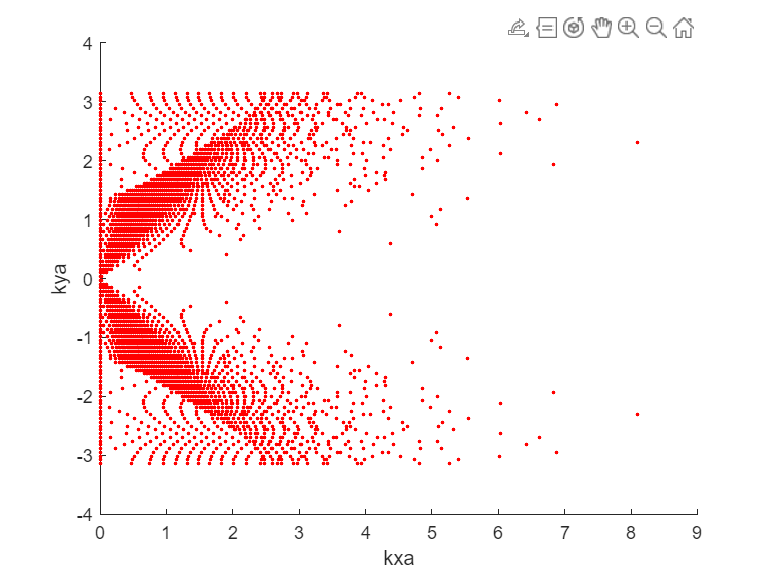

h1=figure;
hold on
for i = 1:n*m
    omega_=Result2(i,1);
    kxa_=Result2(i,2);
    kya_=Result2(i,3);
    if imag(kxa_)==0
        plot3(real(kxa_),real(kya_),real(omega_),'b.')
    else
        plot3(imag(kxa_),real(kya_),real(omega_),'r.')
    end
end
xlabel('kxa')
ylabel('kya')
zlabel('omega')